# Assignment M3.2

Q1) The **Hazen-Williams equation** is used to estimate the velocity of water in a circular pipe:


$$U = 0.849 C R^{0.63} S^{0.54}$$


where:

- U = flow velocity (m/s)

- C = Hazen-Williams roughness coefficient (unitless)

- R = hydraulic radius (m), calculated as R = D/4 for full-flowing circular pipe

- S = pipe slope (m/m)

- D = pipe diameter (m)

The following table provides the data for five different pipes:

**Tasks:**

Write a MATLAB script that:

- Stores the pipe data in a matrix where each row corresponds to a pipe and the columns represent diameter, slope, and roughness.

- Computes the hydraulic radius R and the velocity U for each pipe.

- Appends the computed velocity as the fourth column.

- Displays a table of inputs and results in a formatted way (with appropriate headers).

%Q1
pipe_data = [0.8,0.002,130; %pipe 1
             0.6,0.0015,140; %pipe 2
             1.0,0.0022,120; %pipe 3
             0.5,0.003,110; %pipe 4
             0.75,0.0018,135] %pipe 5

pipe_data =     0.8000    0.0020  130.0000
    0.6000    0.0015  140.0000
    1.0000    0.0022  120.0000
    0.5000    0.0030  110.0000
    0.7500    0.0018  135.0000



D = pipe_data(:,1)

D =     0.8000
    0.6000
    1.0000
    0.5000
    0.7500


S = pipe_data(:,2)

S =     0.0020
    0.0015
    0.0022
    0.0030
    0.0018


C = pipe_data(:,3)

C =    130
   140
   120
   110
   135



R = D ./ 4

R =     0.2000
    0.1500
    0.2500
    0.1250
    0.1875



U = 0.849 .* C .* (R.^0.63) .* (S.^0.54)

U =     1.3965
    1.0741
    1.5621
    1.0940
    1.3155



pipe_data = [pipe_data, U]

pipe_data =     0.8000    0.0020  130.0000    1.3965
    0.6000    0.0015  140.0000    1.0741
    1.0000    0.0022  120.0000    1.5621
    0.5000    0.0030  110.0000    1.0940
    0.7500    0.0018  135.0000    1.3155



T = table((1:height(pipe_data)).', D, S, C, U, 'VariableNames', {'Pipe','Diameter (m)','Slope (S)','Roughness (C)','Flow Velocity (m/s)'});

disp(T);

    Pipe    Diameter (m)    Slope (S)    Roughness (C)    Flow Velocity (m/s)
    ____    ____________    _________    _____________    ___________________

     1           0.8          0.002           130               1.3965       
     2           0.6         0.0015           140               1.0741       
     3             1         0.0022           120               1.5621       
     4           0.5          0.003           110                1.094       
     5          0.75         0.0018           135               1.3155       



Q2) A simply supported beam of length 10 meters is subjected to a combination of point and distributed loads. The **displacement** (in mm) along the beam can be approximated using singularity functions:


$$u(x) = -\frac{5}{600} \langle x - 2 \rangle^4 + \frac{1}{1500} \langle x - 6 \rangle^3 + 0.75 \langle x - 5 \rangle^2 + \frac{57}{600} x^3 - 2.3825x$$


where


$$\[
\langle x - a\rangle^n =
\begin{cases}
(x - a)^n, & x > a,\\
0, & x \le a
\end{cases}
\]$$


Write a MATLAB program that:

- **Defines a function** sing(x, a, n) to implement the singularity function $\langle x - a \rangle^n$. (Use an if statement inside this function)

- Creates a **vector of x values** from 0 to 10.

- Computes the **displacement** u(x) using the formula above.

- Plots the displacement vs. x. Add axis labels and a title.

%Q2
function out = sing(x, a, n)

x =      0     1     2     3     4     5     6     7     8     9    10


    out = zeros(size(x));
    idx = x > a;
    out(idx) = (x(idx) - a).^n;
end

T = 11×2 table
    x (m)    u(x) (mm)
    _____    _________

      0             0 
      1       -2.2875 
      2        -4.005 
      3       -4.5908 
      4       -3.5833 
      5       -0.7125 
      6        4.8417 
      7          13.7 
      8        25.535 
      9        39.822 
     10        55.834 


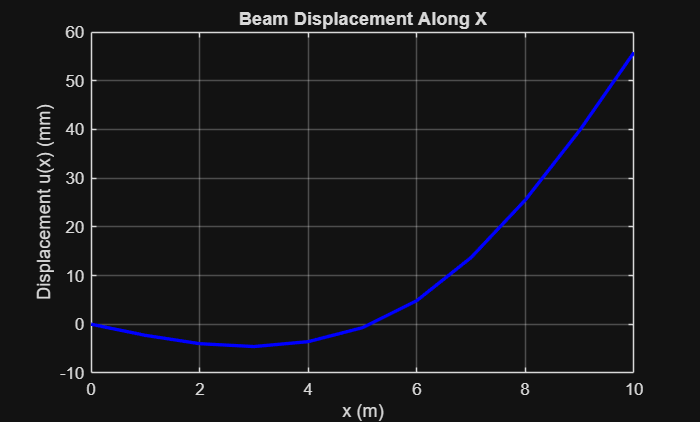


x = 0:1:10

u = -5/600*sing(x,2,4) + 1/1500*sing(x,6,3) + 0.75*sing(x,5,2) + (57./600)*x.^3 - 2.3825*x;

T = table(x', u', 'VariableNames', {'x (m)', 'u(x) (mm)'})
disp(table)


plot(x,u,'b-','LineWidth', 2)
xlabel('x (m)')
ylabel('Displacement u(x) (mm)')
title('Beam Displacement Along X')
grid on
